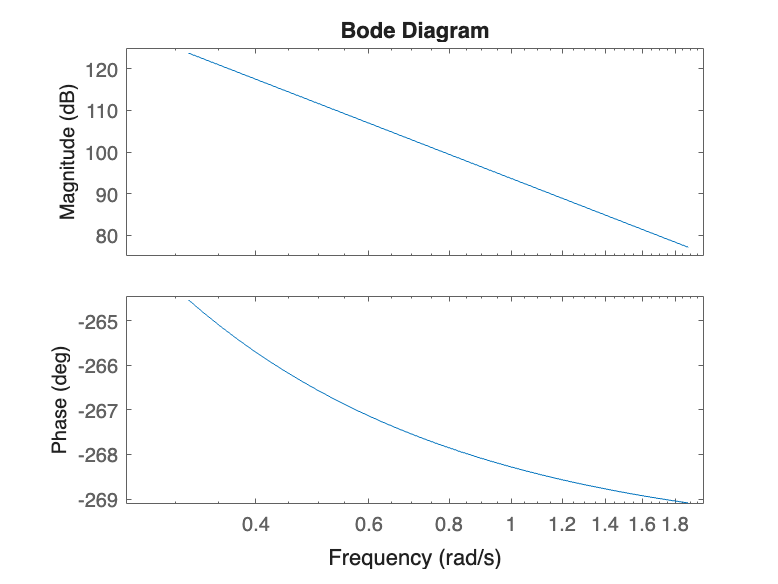

%% Parameters
rho   = 1000;     % kg/m^3
g     = 9.8;      % m/s^2

% a) Third-order shifted integrator (mag-shaper)
alpha = 0.01;   K = rho*g^2/2;
Hmag = tf(K, [1,3*alpha,3*alpha^2,alpha^3]);
bode(Hmag,{0.05*2*pi,0.3*2*pi})

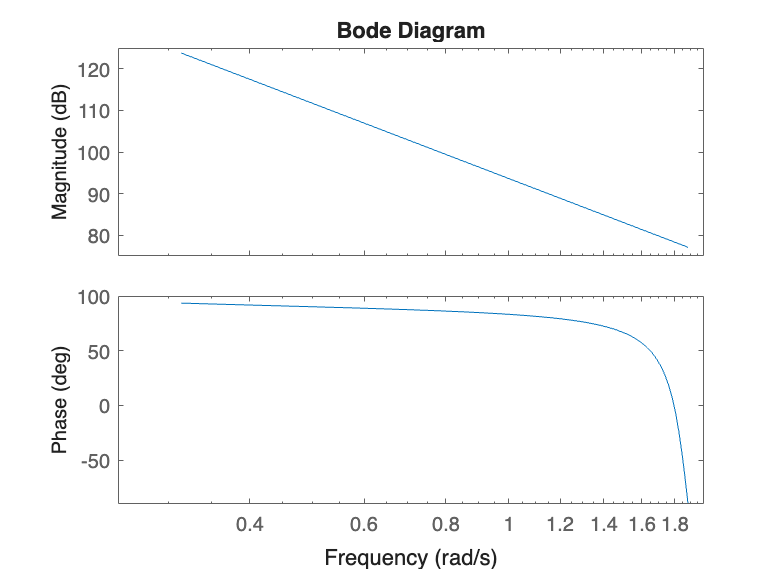


% b) Second-order all-pass for –90° shift
f0      = 0.15;          % Hz
w0      = 2*pi*f0;       % rad/s
zeta_ap = 0.02;          % small damping → flat phase around w0
Aap = tf([1, -2*zeta_ap*w0, w0^2], [1,  2*zeta_ap*w0, w0^2]);
bode(Aap,{0.05*2*pi,0.3*2*pi})

% c) Total H(s)
Htot = series(Hmag, Aap);
bode(Htot, {0.05*2*pi,0.3*2*pi});  % mag ~1/ω^3, phase ~ –360°≈0°


Den=cell2mat(Htot.Denominator);
Num=cell2mat(Htot.Numerator);